# **Inverted Pendulum on a Cart**

The system in this example consists of an inverted pendulum mounted to a motorized cart. The inverted pendulum system is an example commonly found in control system textbooks and research literature. Its popularity derives in part from the fact that it is unstable without control, that is, the pendulum will simply fall over if the cart isn't moved to balance it. Additionally, the dynamics of the system are nonlinear. The objective of the control system is to balance the inverted pendulum by applying a force to the cart that the pendulum is attached to. A real-world example that relates directly to this inverted pendulum system is the attitude control of a booster rocket at takeoff.

## Modelling

In this case we will consider a two-dimensional problem where the pendulum is constrained to move in the vertical plane shown in the figure below. For this system, the control input is the force $F$ that moves the cart horizontally and the outputs are the angular position of the pendulum  and the horizontal position of the cart $x$.

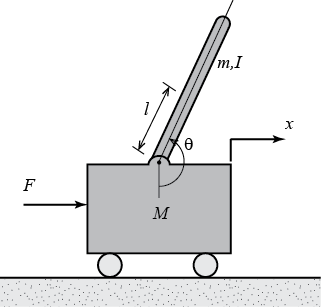

We will define a few variables that are already defined as part of the problem. More than often you won't have the data of the system available, and you'll have to measure it or even, at some times, estimate it.

$M$             `mass of the cart `$[kg]$

$m$`       mass of the pendulum `$[kg]$

$I$               `moment of intertia of the pendulum `$\left[\frac{kg}{m^2}\right]$

$F$              `force applied to the cart `$[N]$

$\theta$       `    pendulum angle to the cart `$[rad]$

$x$               `cart position `$[m]$

$l$`        length to the pendulum's mass center `$[m]$

$b$               `dynamic coefficient of friction of the cart `$\left[\frac{N}{m.s}\right]$

### System Requirements

Also, we will define a few constraints for the design. After, the modeling we should design our controller to meet the specified criteria.

- The setting time for the `angle(`$\theta$) and the cart position ($x$) should be less than 5 s

- `The `$\theta$ must not deviate further than 0.05 rad.

- The rise time for $x$ should be less than 0.5 s.

- Steady-state error should be at most 2% for $x$ and $\theta$.

### System Kinematics

Once we've defined the system qualitative—by its free-body diagram—we must translate this into equations. First off, we should start from Newton's second law, right?


$$\sum^N_{i=0} F_i = m \cdot \vec{a}$$


Since this problem is 1-dimensional, the axis in which the cart translates is going to be $x$ as defined above. Keep in mind even though we do have a force pointing downwards due to the mass of the cart, it's counteracted by the normal force pointing upwards caused by the floor—it isn't drawn in the free-body mass diagram— so the kinematics in the $y$ axis isn't taken into account.

Thus, we will have our first equation for the kinematics on the $x$ axis defined by the following.


$$F = M\vec{a} + b\vec{v} + N$$


Just a quick note. We're redefining the variable names with a different notation generally used in control theory; in particular, in state-space modeling. 

As we previoulsy defined, $x$ is the position of the cart, and from physics we also know that $\vec{x} = \frac{d\vec{v}}{dt}$ and $\vec{v} = \frac{d\vec{a}}{dt}$. For the sake of the notation, and to keep things more simple, we're going to define derivatives with respect to time $(t)$ with a dot on top of the variable, e. g. $\dot{x}$ for the derivative of the position with respect to time, and that is the velocity. Additionally, we're going to omit the vector notation, but we all know these are vectors that have a magnitude and direction.

Therefore, the equation is again defined as:


$$F = M\ddot{x} + b\dot{x} + N$$


Secondly, we could talk a little bit about the pendulum. The pendulum is a rigid body whose mass is $m$. The coordinates of the center of mass is defined by the tuple $(x_p, y_p)$; although, the coordinate $y_p$ is of no interest as the problem happens in the one axis. Then, we could define the position of the center of mass as a function of the cart position $x$.


$$x_p = x + l\sin(\theta)$$


If we derivate this function respect to time, we get the acceleration of the pendulum's center of mass given by


$$\ddot{x_p} = \ddot{x} - l\sin(\theta)\dot{\theta}^2 + l\cos(\theta)\ddot{\theta}$$


We can also define the pendulum kinematics based on Netwon's second law of motion. Take a look.


$$N = m\ddot{x}_p$$


Replacing $\ddot{x}_p$ we get the following equation:


$$N = m\ddot{x} - ml\sin(\theta)\dot{\theta}^2 + ml\cos(\theta)\ddot{\theta}$$


If we then combine the kinematics of the pendulum and the kinematics of the cart, we get a single non-linear equation with both angle of the pendulum and position the position of the cart.


$$(M+m)\ddot{x} + b\dot{x} + ml\cos(\theta)\ddot{\theta} - ml\sin(\theta)\dot{\theta}^2 = F$$


Of course, we do now need to work out the second equation of motion to have a compatible determined system. To do so, we should work with the perpendicular forces.


$$P - mg = m\ddot{y}_p$$


We know $\ddot{y}_p = l\cos(\theta)$, thus


$$P = mg - ml\cos(\theta)\dot{\theta}^2 - ml\sin(\theta)\ddot{\theta}$$


Finally, we should just use the sum of moments equation to get rid of $P$ and $N$.


$$I\ddot{\theta} = Pl\sin(\theta) - Nl\cos(\theta)$$


By replacing $P$ and $N$ on the last equation, we obtain the second equation of motion for the system.


$$(I + ml^2)\ddot{\theta} = mgl\sin(\theta) - ml\cos(\theta)\ddot{x}$$


#### Equations of Motion

After the above steps, we've come up with the two equations of motion of interest.


$$\begin{cases} (M+m)\ddot{x} + b\dot{x} + ml\cos(\theta)\ddot{\theta} - ml\sin(\theta)\dot{\theta}^2 = F
\\
(I + ml^2)\ddot{\theta} = mgl\sin(\theta) - ml\cos(\theta)\ddot{x}
\end{cases}$$


As you can, it's a non-linear system, and in this example we'll work with techniques applied for linear systems. Therefore, we must linearize the system around a given point.

We assume that $\theta = \pi + \phi$ where $\phi$ is the deviation which should be pretty small according to our requirements, and also that $\theta = \pi$ where this is the upward vertical equilibrium point. Thus, we can use the small angles approximation below.


$$\begin{cases}
\cos \theta = \cos(\pi + \phi) \simeq -1 \\
\sin \theta = \sin(\pi + \phi) \simeq - \phi \\
\dot{\theta}^2  = \dot{\phi}^2 \simeq 0
\end{cases}$$


Then, our linearized system is the following


$$\begin{cases} (M+m)\ddot{x} + b\dot{x} - ml\ddot{\phi} = F
\\
(I + ml^2)\ddot{\phi} - mgl\phi = ml\ddot{x}
\end{cases}$$


### State-space Representation

So, we came up with two second order differential equations which can be solved by a numerous techniques. However, the most used technique is called state-space representation of the system, and it brings a lot of advantages over other methods. An example would be representing the two second order differential equations as four first order differential equations—two per each second order differential equation.

We're going to rename the variables so it fits the state-space representation. Since we know that we want four first order differential equations, we're going to assign four new variables to our state vector, namely $\mathbf{x} = (x_1, x_2, x_3, x_4)$.

Below you can find the change of variables.


$$\begin{cases}
x_1 = x \\
x_2 = \dot{x} \\
x_3 = \phi \\
x_4 = \dot{\phi}
\end{cases}$$
                     
$$\begin{cases}
\dot{x_1} = \dot{x} = x_2 \\
\dot{x_2} = \ddot{x} \\
\dot{x_3} = \dot{\phi} = x_4 \\
\dot{x_4} = \ddot{\phi}
\end{cases}$$


Also, $F = u$. With the given change of variables, our linearized system of equations holds


$$

\begin{cases} 
\dot{x_1} = x_2 \\
(M+m)\dot{x_2} + bx_2 - ml\dot{x_4} = u \\
\dot{x_3} = x_4 \\
(I + ml^2)\dot{x_4} - mglx_3 = ml\dot{x_2 \\
\end{cases}$$


By manipulating the second and fourth equation, we can decouple the angle and the position. Ultimately, the state-space representation is defined below.


$$\left[\matrix{\dot{x_1} \cr \dot{x_2} \cr \dot{x_3} \cr \dot{x_4}}\right] = 

\left[\matrix{0 & 1 & 0 & 0 \cr
0 & \frac{-(I+ml^2)b}{I(M+m)+Mml^2} & \frac{m^2gl^2}{I(M+m)+Mml^2} & 0 \cr
0 & 0 & 0 & 1 \cr
0 & \frac{-mlb}{I(M+m)+Mml^2} & \frac{mgl(M+m)}{I(M+m)+Mml^2} & 0 \cr
}\right]

\left[\matrix{x_1 \cr x_2 \cr x_3 \cr x_4}\right] +

\left[\matrix{0 \cr \frac{I+ml^2}{I(M+m)+Mml^2} \cr 0 \cr \frac{ml}{I(M+m)+Mml^2}}\right] u$$



$$\left[\matrix{y_1 \cr y_2}\right] = 

\left[\matrix{1 & 0 & 0 & 0 \cr 0 & 0 & 1 & 0}\right]
\left[\matrix{x_1 \cr x_2 \cr x_3 \cr x_4}\right]$$


## Controller Design

Modeling is quite fun to do, but what good is it if the system that we're designing is unstable? To check that out we need to define values for the variables declared at the beginning. It will allow us to check the poles and zeros of the open and closed-loop system.

M = 0.5;
m = 0.2;
b = 0.2;
I = 0.006;
g = 9.8;
l = 0.3;

Given the data for the variables, we can compute the state matrix $(A)$, the input matrix $(B)$, and the output matrix $(C)$.

d = I*(M+m) + M*m*l^2; % Just storing the denominator in a variable.

A = [
    0 1 0 0;
    0 -(I+m*l^2)*b/d m^2*g*l^2/d 0;
    0 0 0 1;
    0 -m*l*b/d m*g*l*(M+m)/d 0
    ];

B = [0; (I+m*l^2)/d; 0; m*l/d];

C = [1 0 0 0; 0 0 1 0];

D = [0; 0]; % Need to define the feedthrough matrix for later use.

We've just defined the matrices, now we shall create the system object using a MATLAB built-in function called `ss() `based on the matrices`. `

sys = ss(A, B, C, D, ...
    'StateName', {'x', 'x_dot', 'phi', 'phi_dot'}, ...
    'InputName', {'u'}, ...
    'OutputName', {'x', 'phi'});

### Open-loop System

Now we would like to see if the open-loop system is stable. One way to do this is by plotting the poles and zeros.

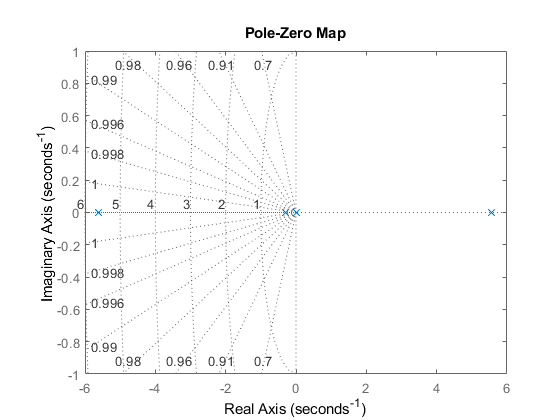

pzmap(sys);
grid on

It's obvious that the pole on the right-half plane (RHP) makes the system unstable. Another way to look at this is by checking the eigenvalues of the state matrix (just solve the characteristic equation $A - \lambda I = 0$). We will just use the built-in function `eig()`.

eig(A)

ans =          0
   -5.6253
   -0.2855
    5.5471


Again, the system isn't stable as we have a positive eigenvalue, and if you take a closer look corresponds to the real part of the pole in the RHP (Yeah, every pole in this system is real).

### Controllability

Before jumping into designing the controller itself, we should check a few things. The question that should arise is, can we control the system to a specific state by providing a specific input? Formally, we can define controlability for a Linear Time-Invariant (LTI) system by saying that an LTI system is controllable if, for every $x_1$, and every $T > 0$, there exists an input function $u(t)$, $0 < t \leq T$, such that the system is taken from $0$ at $t = 0$ to $x_1$ at $t = T$.

#### Controllability Test

To test the controllability we must compute the controllability matrix $(C)$ with the built-in function `ctrb()`. If this matrix has full rank, then the system is controllable.

ctrb(A, B)

ans =          0    1.8182   -0.6612   12.3892
    1.8182   -0.6612   12.3892   -8.9229
         0    4.5455   -1.6529  142.3366
    4.5455   -1.6529  142.3366  -62.8031


rank(ctrb(A, B))

ans = 4

As we can see the matrix has full rank, and so there's no uncontrollable states in this system. We now can proceed to design our controller!

### Linear Quadratic Regulator (LQR)

To control the plant we will do a full-state feedback, this being that every state variable is going to be measured, and used to control both the position of the cart and the angle of the pendulum.

LQR is a technique used in optimal control whose goal is to optimize performance and effort. The system to control has to be a linear system, and the cost function or function is quadratic. The goal of this algorithm is to find the $K$ gain to control the plan by minimizing the cost function specified by ourselves.

The cost function has the form of:


$$J = \int^{\infty}_{0} (x(\tau)^\top Qx(\tau) + u(\tau)^\top R u(\tau) + 2x(\tau)^\top Nu(\tau)) d\tau$$


$Q_f$ is the final state cost, $Q$ is the state cost, $R$ is the input cost, and $N$ is the cross-term cost. The state cost will penalize or reward certain states as well as the input cost will do the same for the certain inputs. These matrices are generally parameters that we have to tune in order to meet the design criteria.

Then, given the system $\dot{x} = Ax + Bu$ the input that minimizes the cost function is $u = -Kx$. Where $K = R^{-1}(B^\top P(t)+N^\top)$, and $P$ is found by solving the [Riccati Differential Equation](https://en.wikipedia.org/wiki/Riccati_differential_equation).

We're going to solve this problem by using the MATLAB function `lqr()`. First, let's define the cost matrices.

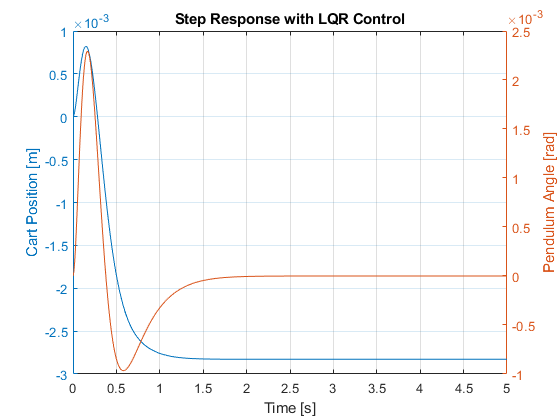

Q = [
    5000 0 0 0;
    0 0 0 0;
    0 0 100 0;
    0 0 0 0;
    ];

R = 1;

K = lqr(A, B, Q, R);

Ac = A - B*K;
Bc = B;
Cc = C;
Dc = D;

closed_loop_sys = ss(Ac, Bc, Cc, Dc, ...
    'StateName', {'x', 'x_dot', 'phi', 'phi_dot'}, ...
    'InputName', {'u'}, ...
    'OutputName', {'x', 'phi'});

t = 0:0.01:5;
r = 0.2 * ones(size(t));

[y, t, ~] = lsim(closed_loop_sys, r, t);

figure('name', 'Step response with LQR')
title('Step Response with LQR Control')
xlabel('Time [s]')
grid on

yyaxis left
plot(t,y(:,1))
ylabel('Cart Position [m]')

yyaxis right
plot(t, y(:, 2))
ylabel('Pendulum Angle [rad]')

xlim('auto')
ylim('auto')

 So we see in our plot that the angle stabilizes pretty quick, at around 1 second. Although, the cart position drifts a little bit from where we commanded. To overcome this problem, we can do two things: 1) add a precompensation $\bar{N}$ or add an integrator ($\int$).

#### Precompensation

To add a precompensation we just need to redefine the closed-loop system a little bit by changing our $B$ matrix.

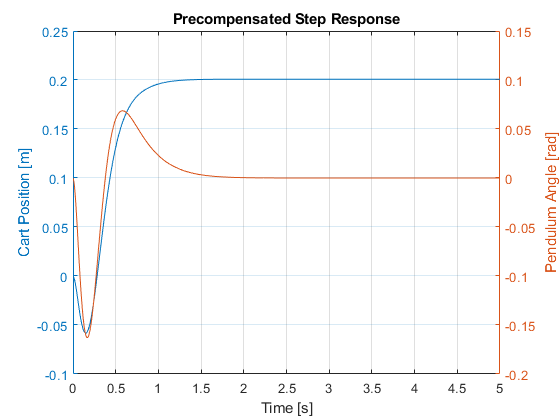

Nbar = -71;

closed_loop_sys = ss(Ac, Bc*Nbar, Cc, Dc, ...
    'StateName', {'x', 'x_dot', 'phi', 'phi_dot'}, ...
    'InputName', {'u'}, ...
    'OutputName', {'x', 'phi'});

t = 0:0.01:5;
r = 0.2 * ones(size(t));

[y, t, ~] = lsim(closed_loop_sys, r, t);

figure('name', 'Precompensated Step Response')
title('Precompensated Step Response')
xlabel('Time [s]')
grid on

yyaxis left
plot(t,y(:,1))
ylabel('Cart Position [m]')

yyaxis right
plot(t, y(:, 2))
ylabel('Pendulum Angle [rad]')

xlim('auto')
ylim('auto')

### Integral Action

The other way is to augment the system with an integrator, which is basically the open-loop state representation.


$$\left[\matrix{\dot{x_1} \cr \dot{x_2} \cr \dot{x_3} \cr \dot{x_4} \cr \dot{q_1}} \right] = 

\left[\matrix{0 & 1 & 0 & 0 & 0\cr
0 & \frac{-(I+ml^2)b}{I(M+m)+Mml^2} & \frac{m^2gl^2}{I(M+m)+Mml^2} & 0 & 0 \cr
0 & 0 & 0 & 1 & 0 \cr
0 & \frac{-mlb}{I(M+m)+Mml^2} & \frac{mgl(M+m)}{I(M+m)+Mml^2} & 0 & 0 \cr
-1 & 0 & 0 & 0 & 0
}\right]

\left[\matrix{x_1 \cr x_2 \cr x_3 \cr x_4 \cr q_1}\right] +

\left[\matrix{0 \cr \frac{I+ml^2}{I(M+m)+Mml^2} \cr 0 \cr \frac{ml}{I(M+m)+Mml^2} \cr 0}\right] u +

\left[\matrix{0 \cr 0 \cr 0 \cr 0 \cr 1}\right] r$$



$$\left[\matrix{y_1 \cr y_2}\right] = 

\left[\matrix{1 & 0 & 0 & 0 & 0 & 0 \cr 0 & 0 & 1 & 0 & 0 & 0}\right]
\left[\matrix{x_1 \cr x_2 \cr x_3 \cr x_4 \cr q_1 }\right]$$


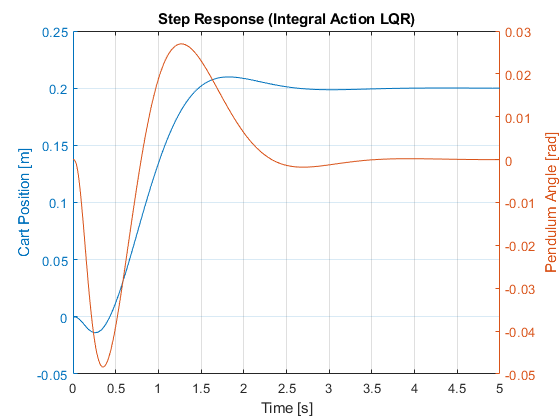

Aa = [A [0; 0; 0; 0]; -C(1,:) 0];
Ba = [B; 0];



Qa = [
    1 0 0 0 0;
    0 1 0 0 0;
    0 0 500 0 0;
    0 0 0 1 0;
    0 0 0 0 3000
    ];

Ra = 0.1;

Ka = lqr(Aa, Ba, Qa, Ra);
Kc = Ka(1:4);
Ki = Ka(5);

Aa = [A - B*Kc -B*Ki; -C(1,:) 0];
Br = [0; 0; 0; 0; 1];
Ca = [C [0; 0]];
Da = D;

closed_loop_augmented_sys = ss(Aa, Br, Ca, Da, ...
    'StateName', {'x', 'x_dot', 'phi', 'phi_dot', 'q1'}, ...
    'InputName', {'u'}, ...
    'OutputName', {'x', 'phi'});

t = 0:0.01:5;
r = 0.2 * ones(size(t));

[y, t, ~] = lsim(closed_loop_augmented_sys, r, t);

figure('name', 'Step Response (Integral Action LQR)')
title('Step Response (Integral Action LQR)')
xlabel('Time [s]')
grid on

yyaxis left
plot(t,y(:,1))
ylabel('Cart Position [m]')

ylim('auto')
xlim('auto')

yyaxis right
plot(t, y(:, 2))
ylabel('Pendulum Angle [rad]')

xlim('auto')
ylim('auto')

We can see that we meet the requirements, and the controller behaves quite well. Although, adding an integral action slows it down a little bit at the expense of being robust to certain disturbances.

### Observability

More than often our state vector cannot be fully measured; even at times the state cannot be measured at all. Therefore, if we wanted to design a full-state feedback controller it wouldn't be feasible. Luckily, we can perform this technique by estimating the state vector. 

There are many state observers, such as the Luenberger Observer and the Kalman Filter. The latter is the optimal state observer, but it won't be part of this script. Instead, we're going to implement the Luenberger observer.

Before actually implementing the observer, we should check the observability of the system (the same way we checked for controllability).

O = obsv(A, C)

O =     1.0000         0         0         0
         0         0    1.0000         0
         0    1.0000         0         0
         0         0         0    1.0000
         0   -0.3636    2.6727         0
         0   -0.9091   31.1818         0
         0    0.1322   -0.9719    2.6727
         0    0.3306   -2.4298   31.1818


rank(O)

ans = 4

Ok, good news. The system is observable! We can now proceed to estimate the state. The following equation describes the dynamics of the esimated state based on $u$ and $y$, input and ouput respectively.


$$\dot{\hat{\mathbf{x}}} = A\mathbf{x} + B\mathbf{u} + L(\mathbf{y} - \hat{\mathbf{y}})$$


 Also, given that we define the error as $\mathbf{e} = \mathbf{x} - \hat{\mathbf{x}}$, we can compute the dynamics of the error by manipulating the above equations a little bit. Just a quick reminder: keep in mind that $\hat{\mathbf{y}} = C\hat{\mathbf{x}}$ if you want to work out the dynamics of the error.


$$\dot{\mathbf{e}} = (A - LC)\mathbf{e}$$


If the $(A, C)$ pair is observable, we can place the eigenvalues in the left-half plane to make the $A - LC$ stable, and make the error approach to zero.

In general, we would like that our observer is much faster than our controller in terms of convergence. We do this by choosing the poles for the observer faster than the slowest pole of the closed-loop system; take into account that going to hard on the convergence speed can be troublesome, so there's a rule of thumb that says that we should choose the poles 4-10 times faster.

Let's check the cloosed-loop poles.

eig(Ac)

ans =   -8.4925 + 7.9268i
  -8.4925 - 7.9268i
  -4.7591 + 0.8310i
  -4.7591 - 0.8310i


Ok, the slowest poles have a real part of `-4.7591`. So let's place our poles at around `-40`. 

But before doing so, we can look at the form of the $A - LC$, and it looks similar to $A - BK$ where we wanted to estimate $K$. To make things easier, we're going to use the `place()` function, but first we should tranpose $A - LC$ to make it look like the $K$ gain problem, and then compute the $L$ gain. 

poles = [-40 -41 -42 -43];
L = place(A', C', poles)'

L = 	1.0e+03 *

    0.0825   -0.0010
    1.6878   -0.0400
   -0.0019    0.0831
   -0.1146    1.7573


Oh, just to ease your mind. The eigenvalues of $A - LC$ remain unchanged by applying the transpose, so we're good.

#### Observer-based System

Now that we have solved quite a few problems, we're going to describe the state space representation of the complete system with integral action included.


$$\left[
\matrix{
\dot{\mathbf{x}} \cr
\dot{\mathbf{q}} \cr
\dot{\mathbf{e}}
}
\right] =

\left[
\matrix{A & 0 \cr 
-C & 0 \cr
0 & A - LC}
\right]

\left[
\matrix{\mathbf{x} \cr 
\mathbf{q} \cr
\mathbf{e}}
\right] +

\left[
\matrix{B \cr 0}
\right] u +

\left[
\matrix{0 \cr 1 \cr 0}
\right] r$$



$$\mathbf{y} = \left[
\matrix{C & 0}
\right]

\left[
\matrix{\mathbf{x} \cr 
\mathbf{q} \cr
\mathbf{e}}
\right]$$


If you run the simulation without compensation or integral action, you'll get a response with steady-state error like before. 

Af = [
      A zeros(size(A)) zeros(4, 1);
      -C(1,:) [0 0 0 0 0];
      zeros(size(A)) zeros(4, 1) A-L*C
     ];
Bf = [B; zeros(5, 1)];
Cf = [C zeros(size(C)) zeros(2, 1)];
Df = D;
Br = [0; 0; 0; 0; 1; 0; 0; 0; 0];

Qf = [
    200 0 0 0 0 0 0 0 0;
    0 0 0 0 0 0 0 0 0;
    0 0 0 0 0 0 0 0 0;
    0 0 0 0 0 0 0 0 0;
    0 0 0 0 10000 0 0 0 0;
    0 0 0 0 0 0 0 0 0;
    0 0 0 0 0 0 0 0 0;
    0 0 0 0 0 0 0 0 0;
    0 0 0 0 0 0 0 0 0;
    ];

Rf = 0.001;

Kf = lqr(Af, Bf, Qf, Rf);

Now that we've computed the gains with LQR we're going to close the loop as usual.

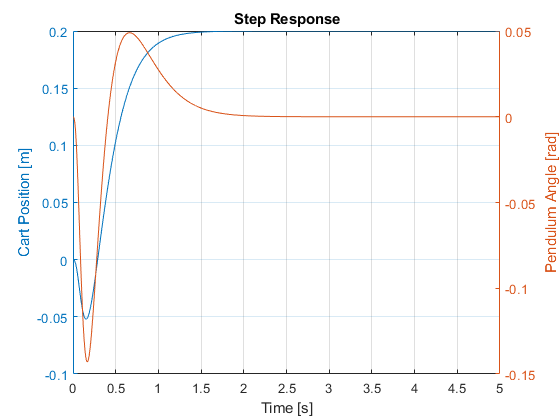

full_sys = ss(Af-Bf*Kf, Br, Cf, Df);

t = 0:0.01:5;
r = 0.2 * ones(size(t));

[y, t, ~] = lsim(full_sys, r, t);

figure('name', 'Step Response')
title('Step Response')
xlabel('Time [s]')
grid on

yyaxis left
plot(t,y(:,1))
ylabel('Cart Position [m]')

ylim('auto')
xlim('auto')

yyaxis right
plot(t, y(:, 2))
ylabel('Pendulum Angle [rad]')

xlim('auto')
ylim('auto')

Success! We've designed a observer-based LQR controller for the inverted pendulum on a cart. Check out the [simulation](matlab:open('..\models\Full_Observer_Based_Controller.slx')) on Simulink as well.

One final thought: look how powerful is the state-space representation, and all the things we've achieved with it.